%sag generation
X = zeros(200,1280);
%X(2,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x;
%X(1,:) = (1+a*(u(t-t1)-u(t-t2))).*x;

i = 1;
%for i = 1:200
    for a = 0.01:0.01:0.1    % alpha parameter
        for A = 0.5:0.1:2.5     %duration of disturbance
            %for t2 = 0.15:0.05:0.35    %ending time stamp of disturbance
                t = 0:0.0003125:0.4-0.0003125;
                %A = 1;
                %a = 0.2;
                f = 50;
                w = 2*pi*f;
                x = A*sin(w.*t);
                u = inline('t>=0');
                %t1 = t2 - d;
                X(i,:) = x;
                i = i+1;
            end
        end
    %end
%end

X

X =          0    0.0490    0.0975    0.1451    0.1913    0.2357    0.2778    0.3172    0.3536    0.3865    0.4157    0.4410    0.4619    0.4785    0.4904    0.4976    0.5000    0.4976    0.4904    0.4785    0.4619    0.4410    0.4157    0.3865    0.3536    0.3172    0.2778    0.2357    0.1913    0.1451    0.0975    0.0490    0.0000   -0.0490   -0.0975   -0.1451   -0.1913   -0.2357   -0.2778   -0.3172   -0.3536   -0.3865   -0.4157   -0.4410   -0.4619   -0.4785   -0.4904   -0.4976   -0.5000   -0.4976
         0    0.0588    0.1171    0.1742    0.2296    0.2828    0.3333    0.3806    0.4243    0.4638    0.4989    0.5292    0.5543    0.5742    0.5885    0.5971    0.6000    0.5971    0.5885    0.5742    0.5543    0.5292    0.4989    0.4638    0.4243    0.3806    0.3333    0.2828    0.2296    0.1742    0.1171    0.0588    0.0000   -0.0588   -0.1171   -0.1742   -0.2296   -0.2828   -0.3333   -0.3806   -0.4243   -0.4638   -0.4989   -0.5292   -0.5543   -0.5742   -0.5885   -0.5971   -0.6000   -0

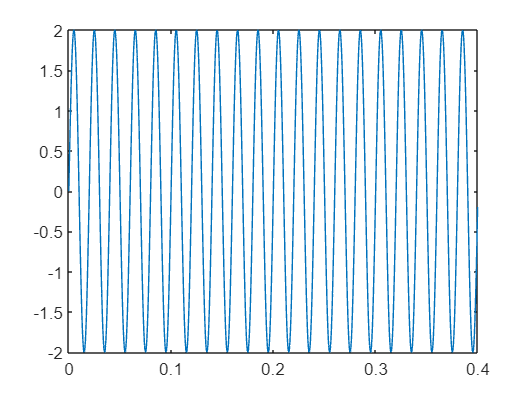

            
plot(t,X(121,:)) 

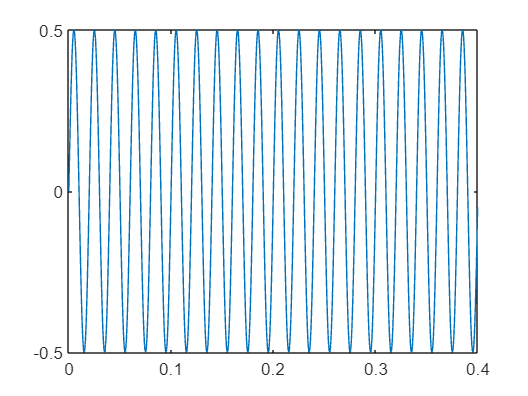

plot(t,X(1,:))

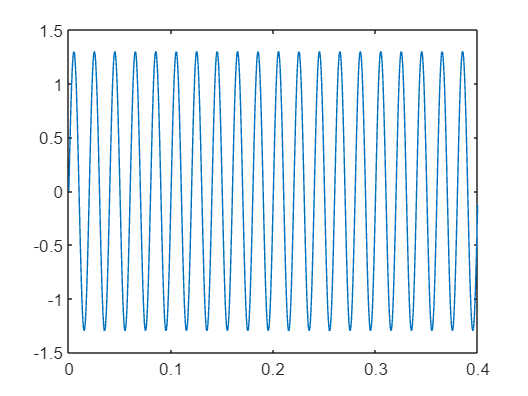

plot(t,X(30,:))

%X(167,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x
%plot(t,x1)

